# try a different map approach

latlim=[20 40];
lonlim=[25 50];
land = readgeotable("landareas.shp");

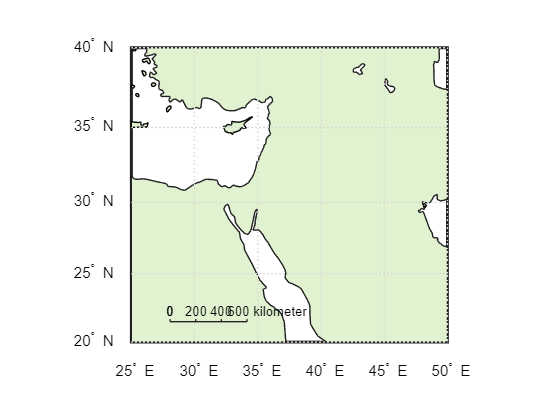

figure;
axm=worldmap(latlim,lonlim);
%geoshow(land,"FaceColor",[0.88 0.95 0.81])
setm(axm,'MapProjection','mercator')
geoshow(land,"FaceColor",[0.88 0.95 0.81])
sc=scaleruler("Units","kilometer");
setm(sc,'majorTick',0:200:600,"MinorTick",0:0)

% figure;
% axm=worldmap(latlim,lonlim);
% geoshow(land,"FaceColor",[0.88 0.95 0.81])
% axm.Projection="orthographic";


plotm(cairo(1),cairo(2),"om",MarkerFaceColor="m")
plotm(tiberias(1),tiberias(2),"om",MarkerFaceColor="m")
hq=quiverm(tiberias(1),tiberias(2),cairo(1)-tiberias(1),cairo(2)-tiberias(2));


% anArrow = annotation('arrow') ;
% anArrow.Parent = gca;
% anArrow.Position = [tiberias(2), tiberias(1),  cairo(2)-tiberias(2), cairo(1)-tiberias(1)] ;
%arrow(tiberias,cairo)
%xx=([cairo(1) tiberias(1)]-lonlim(1))./diff(latlim);
%yy=([cairo(2) tiberias(2)]-latlim(1))./diff(lonlim);

%annotation("arrow",[0.2 0.8],[0.5 0.6])
%geoshow([tiberias(1) cairo(1)],[tiberias(2) cairo(2)])



[A,RA] = readBasemapImage("satellite",latlim,lonlim);
%[x,y] = projfwd(RA.ProjectedCRS,[,lon);


G = digraph(T.Origin,T.Dest,T.NumFlights);

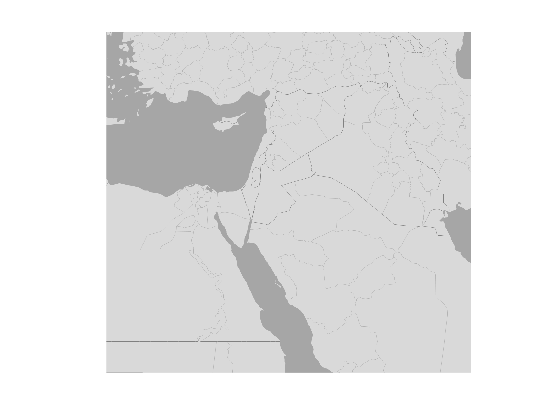


figure; 
mapshow(A,RA)
axis off
%[xc,yc] = projfwd(RA.ProjectedCRS,cairo(2),cairo(1));
hold on
plot(xc,yc)


%%5

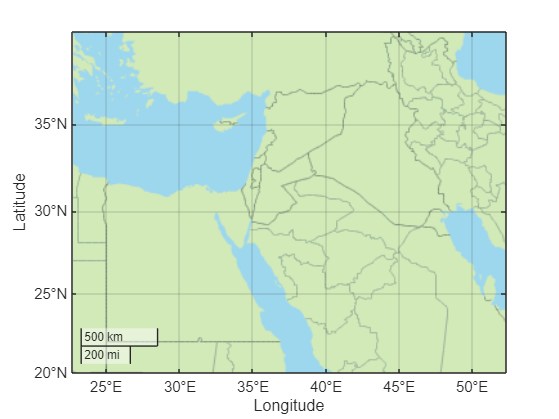

figure;
geobasemap("bluegreen")
geolimits(latlim,lonlim)